clc; clearvars;

Set parameters

paramPath = "C:\Users\tely1\OneDrive\Desktop\EEJ9903\signal_analysis\systemParam.mat";
load(paramPath);

params.lambda = 2.991e-7;

Load real data

addpath(genpath("C:\Users\tely1\OneDrive\Matlab Onedrive\O3_Lidar\proc_functions"))
dataPath = "C:\Users\tely1\Downloads\20260423";

data_format     = "bin";
prefix = "ol";

[scaled_data,times,configs] = read_lidar_datafiles(dataPath,data_format,prefix);
scaled_data = scaled_data(1:8000,:,1:2,:);

times = times(:,2);

num_bins = size(scaled_data,1);
num_files = size(scaled_data,2);
num_devices = size(scaled_data,3);

dz = 3.75;
h = (dz.*(1:num_bins))';
hkm = h./1000;

id = 1;
TR = 1;


td = 270;
data_an = scaled_data(:,:,:,1);
data_pc = scaled_data(:,:,:,2);
data_pc = data_pc./(1-data_pc/td);

bg_an = mean(data_an(7000:end,:,:),1);
bg_pc = mean(data_pc(7000:end,:,:),1);

an = data_an - bg_an;
pc = data_pc - bg_pc;

pc_cnvt = NaN(size(pc));

for i = 1:num_files
    for j = 1:num_devices
        try
            pc_cnvt(:,i,j) = glue_an_pc(an(:,i,j),pc(:,i,j),3,60);
        catch ME
            disp(['error on file ', num2str(i), ', TR, ', num2str(j)]);
        end
    end
end

pc_287 = pc_cnvt(:,id,1);
pc_299 = pc_cnvt(:,id,2);

load("C.mat")
C_287 = (interp1(C_grid,C_287(:,1),h) - CB_287) .* 1e-6;
C_299 = (interp1(C_grid,C_299(:,1),h) - CB_299) .* 1e-6;

% C = C(:,1).*eta_test;
% C(C<1) = NaN;

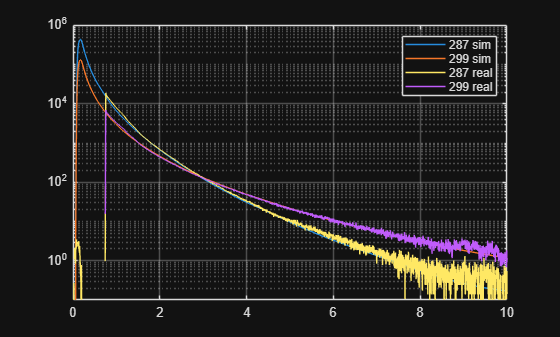

x_lim = [0 10];

figure;
semilogy(hkm,C_287,'DisplayName','287 sim')
hold on
semilogy(hkm,C_299,'DisplayName','299 sim')
plot(hkm,pc_287,'DisplayName','287 real')
plot(hkm,pc_299,'DisplayName','299 real')

hold off
legend
grid on
xlim(x_lim)
ylim([1e-1 1e6])

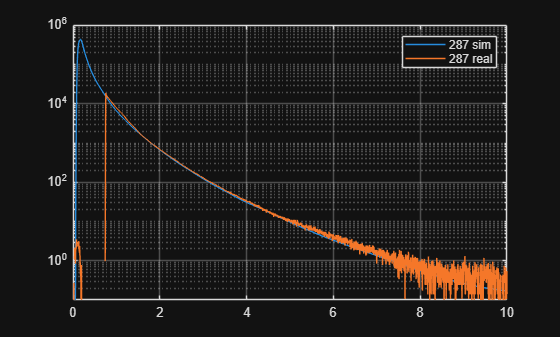

figure;
semilogy(hkm,C_287,'DisplayName','287 sim')
hold on
plot(hkm,pc_287,'DisplayName','287 real')

hold off
legend
grid on
xlim(x_lim)
ylim([1e-1 1e6])

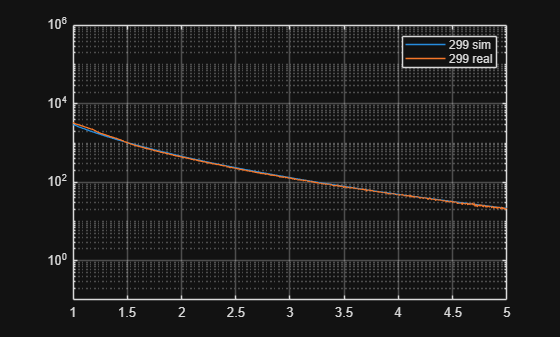

figure;
semilogy(hkm,C_299,'DisplayName','299 sim')
hold on
plot(hkm,pc_299,'DisplayName','299 real')

hold off
legend
grid on
xlim([1 5])
ylim([1e-1 1e6])

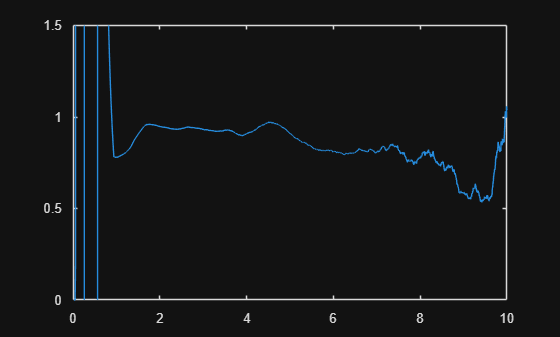

figure;
plot(hkm,C_287./movmean(pc_287,100))
xlim(x_lim)
ylim([0 1.5])

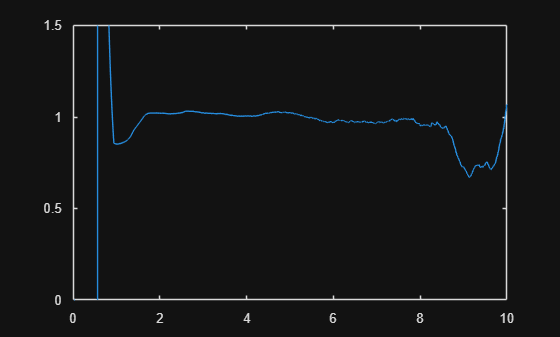

figure;
plot(hkm,C_299./movmean(pc_299,100))
xlim(x_lim)
ylim([0 1.5])